# What should the basis functions be for fitting the raw tongue/lip signals?

Some fluorophores are present at different tissue layers.  The superficial layers (epithelial) contain FAD, NADH, and keratin in certain locations.  These are not going to be impacted by blood absorptions.  The blood is below the epithelial layer.

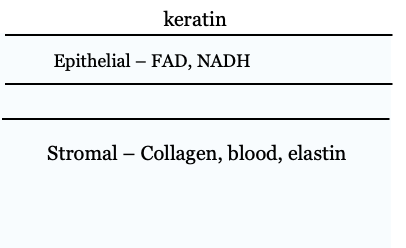

We have data about the excitations of each of these fluorophores.  These are in the isetfluorescence repository.  We are going to read them in and we are also going to read in some examples of raw data taken from our subjects' tongues and lips.  This script will explore how we might create basis functions to predict the raw data as weighted sums of the fluorophore excitations, but combining them as if some of the fluorophores are passing through blood.

The reason we think blood is necessary is because the raw data - directory spectral photometry measures from the tongue and lip - show some signs of the dips that are well known to be part of the blood absorbance (transmittance) measured in different contexts.

To support the calculations of absorbance and transmittance we created a Matlab class called 'medium', which helps us keep track of the relationship between absorbance, absorptance, transmittance and optical density.

## Programming notes

Repositories: isetcam, isetfluorescence and oe_tongue_lip

3/4 of the blood is oxygenated.  We might add in deoxy_ in the future.

## Initialize

Different analyses are based on different wavebands.

ieInit;
wave = 500:600;

## Read in the oxy data

For different purposes we might choose different wavebands.  The raw data are pretty much good from 500-670 or so.  The longer wavelengths are mainly porphyrin fluorescence (bacteria on the tongue).

We only consider oxygenated blood now because 100% of the blood from the heart lung is oxygenated, and about 50% of the blood in the veins is also oxygenated.  So 

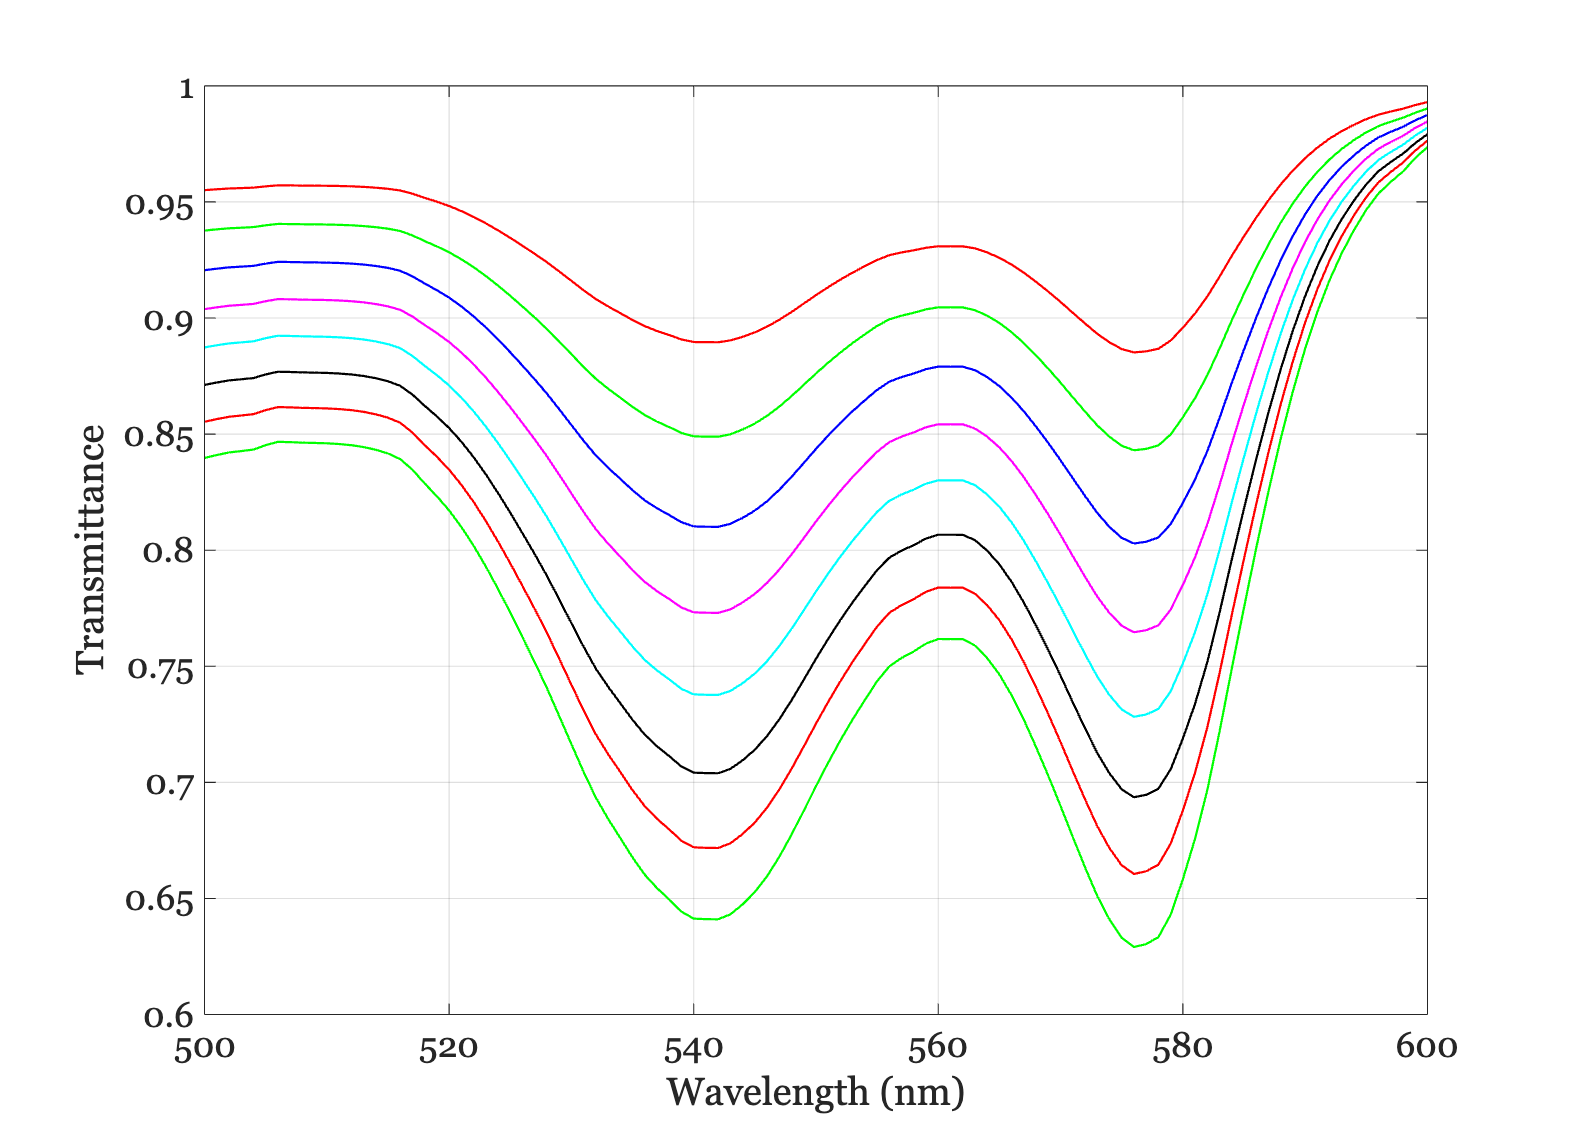

oxyblood = medium('oxy_molarExtinctionCoefficient.mat','wave',wave);

ieNewGraphWin;
for od = (0.5:0.2:2)
    oxyblood.opticalDensity = od;
    plot(wave,oxyblood.transmittance); hold on;
end
grid on; xlabel('Wavelength (nm)'); ylabel('Transmittance');

Notice that the blood has the two characteristic dips at 540 nm and 580nm.  We see little bumps like that in the raw data.

## Load fluorophore emissions

We have many fluorophore files from the literature. These are analyzed in s_LoadFluorophoreMatrix.

For now we read in a few.  More decision making about these to come. 

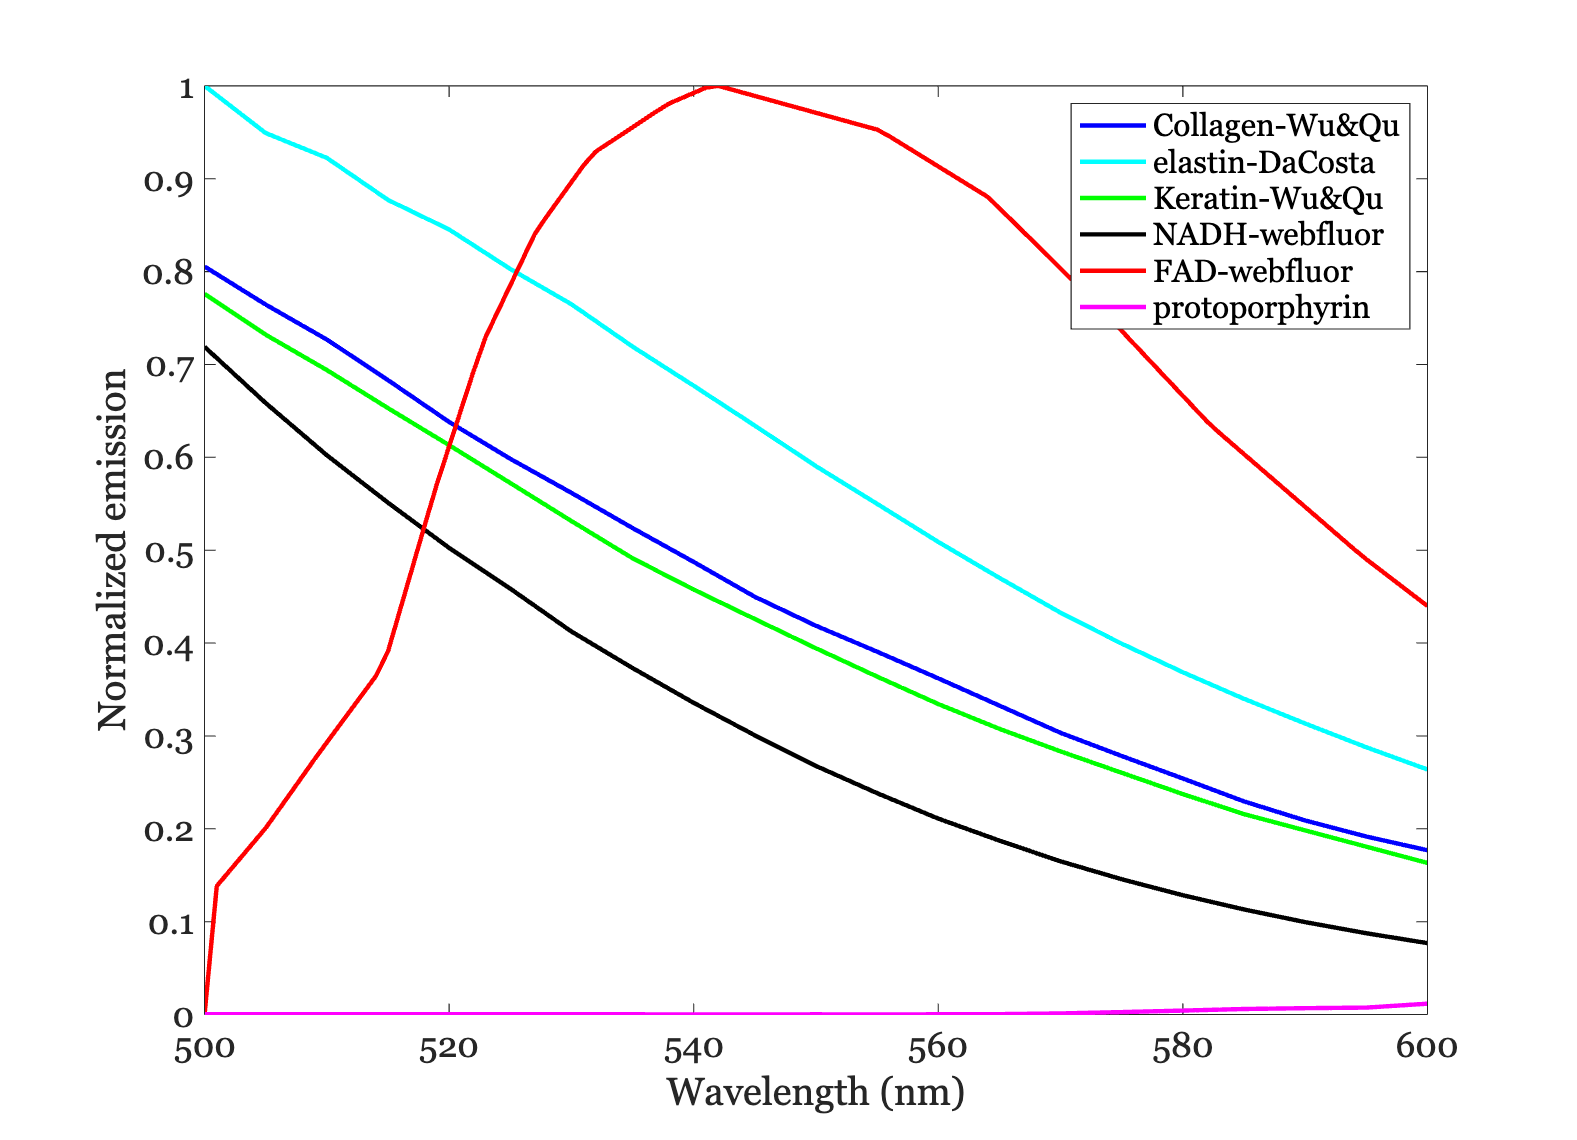

ieNewGraphWin;

collagenF = fiReadFluorophore('CollagenWuQu');
collagen = fluorophoreGet(collagenF,'normalized emission','wave',wave);
plot(wave, collagen,'b','LineWidth',2); hold on;

elastinF = fiReadFluorophore('elastin_webfluor.mat','wave',wave);
elastin = fluorophoreGet(elastinF,'normalized emission','wave',wave);
plot(wave, elastin,'c','LineWidth',2);

keratinF = fiReadFluorophore('KeratinWuQu');
keratin = fluorophoreGet(keratinF,'normalized emission','wave',wave);
plot(wave, keratin,'g','LineWidth',2);

NADHF = fiReadFluorophore('NADH_webfluor.mat'); 
NADH = fluorophoreGet(NADHF,'normalized emission','wave',wave);
plot(wave, NADH,'k','LineWidth',2);hold on; % use this one

FADF = fiReadFluorophore('FADBecker');
FAD = fluorophoreGet(FADF,'normalized emission','wave',wave);
plot(wave,FAD,'r','LineWidth',2);

porphyrinsF = fiReadFluorophore('protoporphyrin');
porphyrins = fluorophoreGet(porphyrinsF,'normalized emission','wave',wave);
plot(wave, porphyrins,'m','LineWidth',2); 

legend('Collagen-Wu&Qu','elastin-DaCosta','Keratin-Wu&Qu','NADH-webfluor','FAD-webfluor','protoporphyrin');
set(gca,'fontsize',16);
xlabel('Wavelength (nm)'); ylabel('Normalized emission')

## Read a couple of raw data sets

We chose Z's data because he has little porphyrin. 

These are measurements with different excitation lights at max intensity.  All the subjects show the peak shift from 500 to 515 as the excitation light changes from 405 to 450.

Also, notice the very large dip on the lip around 580, but not on the tongue. 

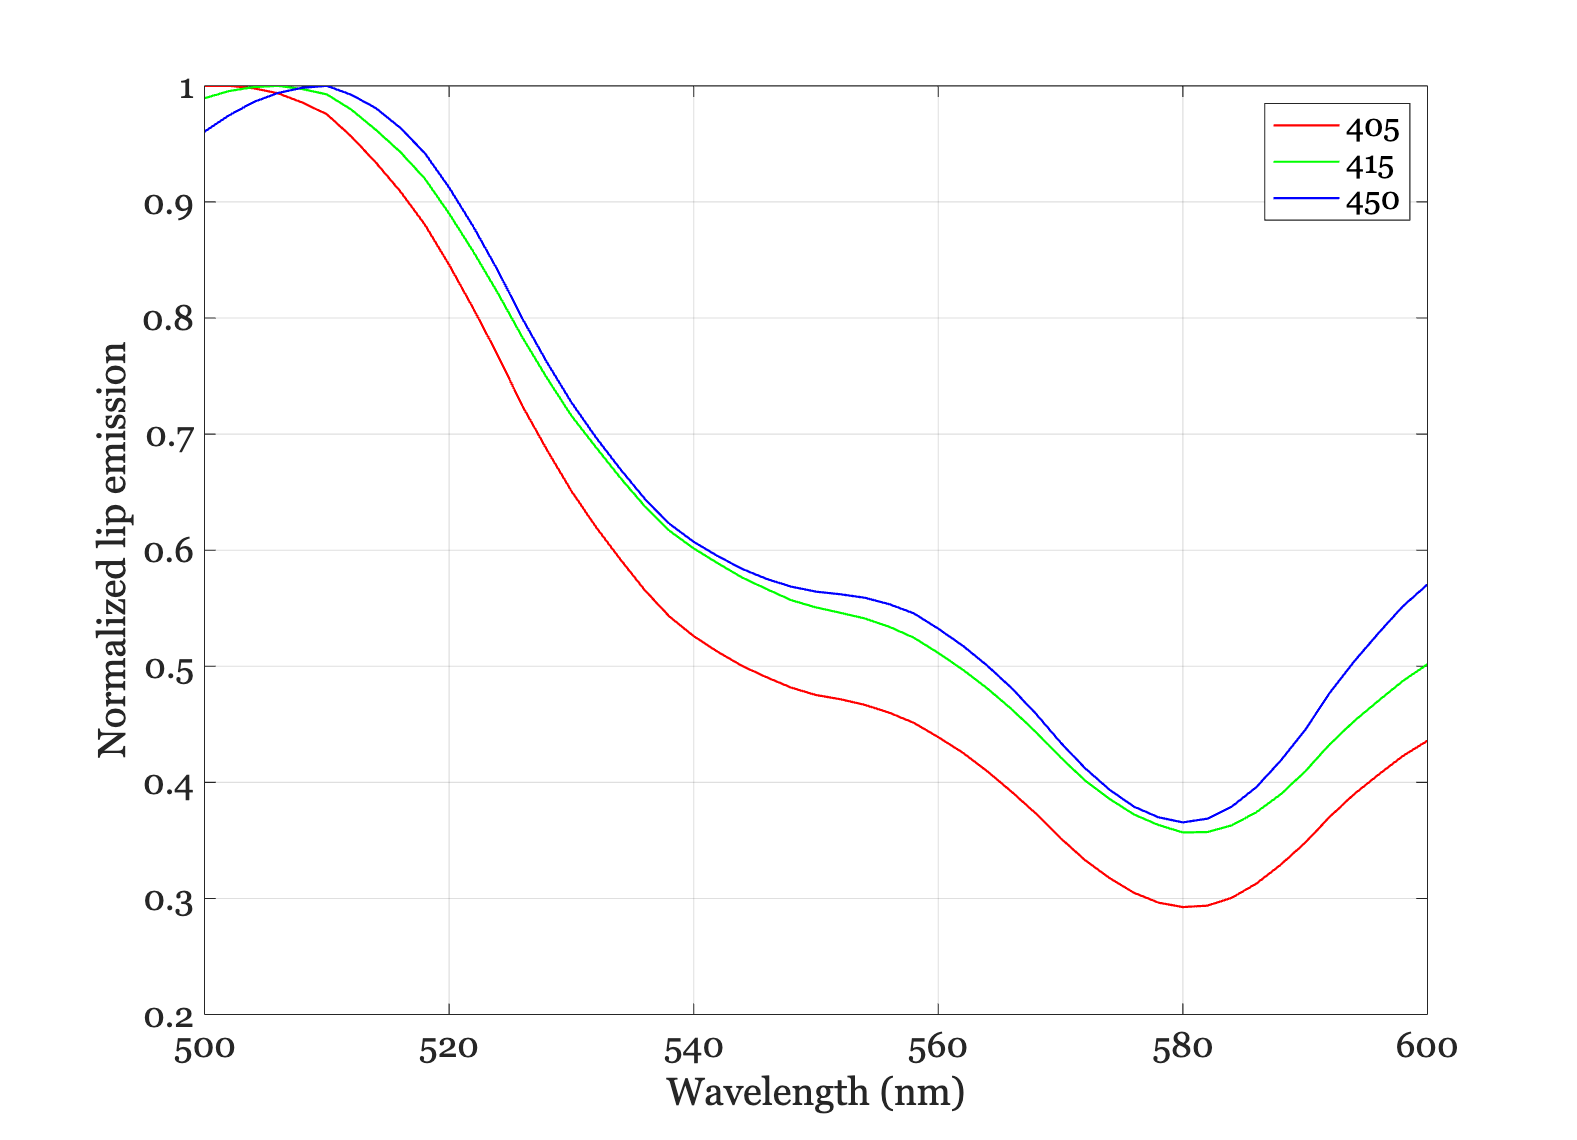

dataDir = fullfile(oeTongueLipRootPath,'data','RawTongueLip');

lipFiles = {'spd-2024-03-14-Z-405nm_lip_980mA.mat';...
    'spd-2024-03-14-Z-415nm_lip_910mA.mat'; ...
    'spd-2024-03-14-Z-450nm_lip_870mA.mat'};
lipData = zeros(numel(wave),numel(lipFiles));

ieNewGraphWin;
for ii=1:numel(lipFiles)
    data = ieReadSpectra(fullfile(dataDir,lipFiles{ii}),wave); 
    lipData (:,ii) = data(:);
    plot(wave,data/max(data(:))); hold on;
end
legend({'405','415','450'});
xlabel('Wavelength (nm)'); ylabel('Normalized lip emission'); grid on;

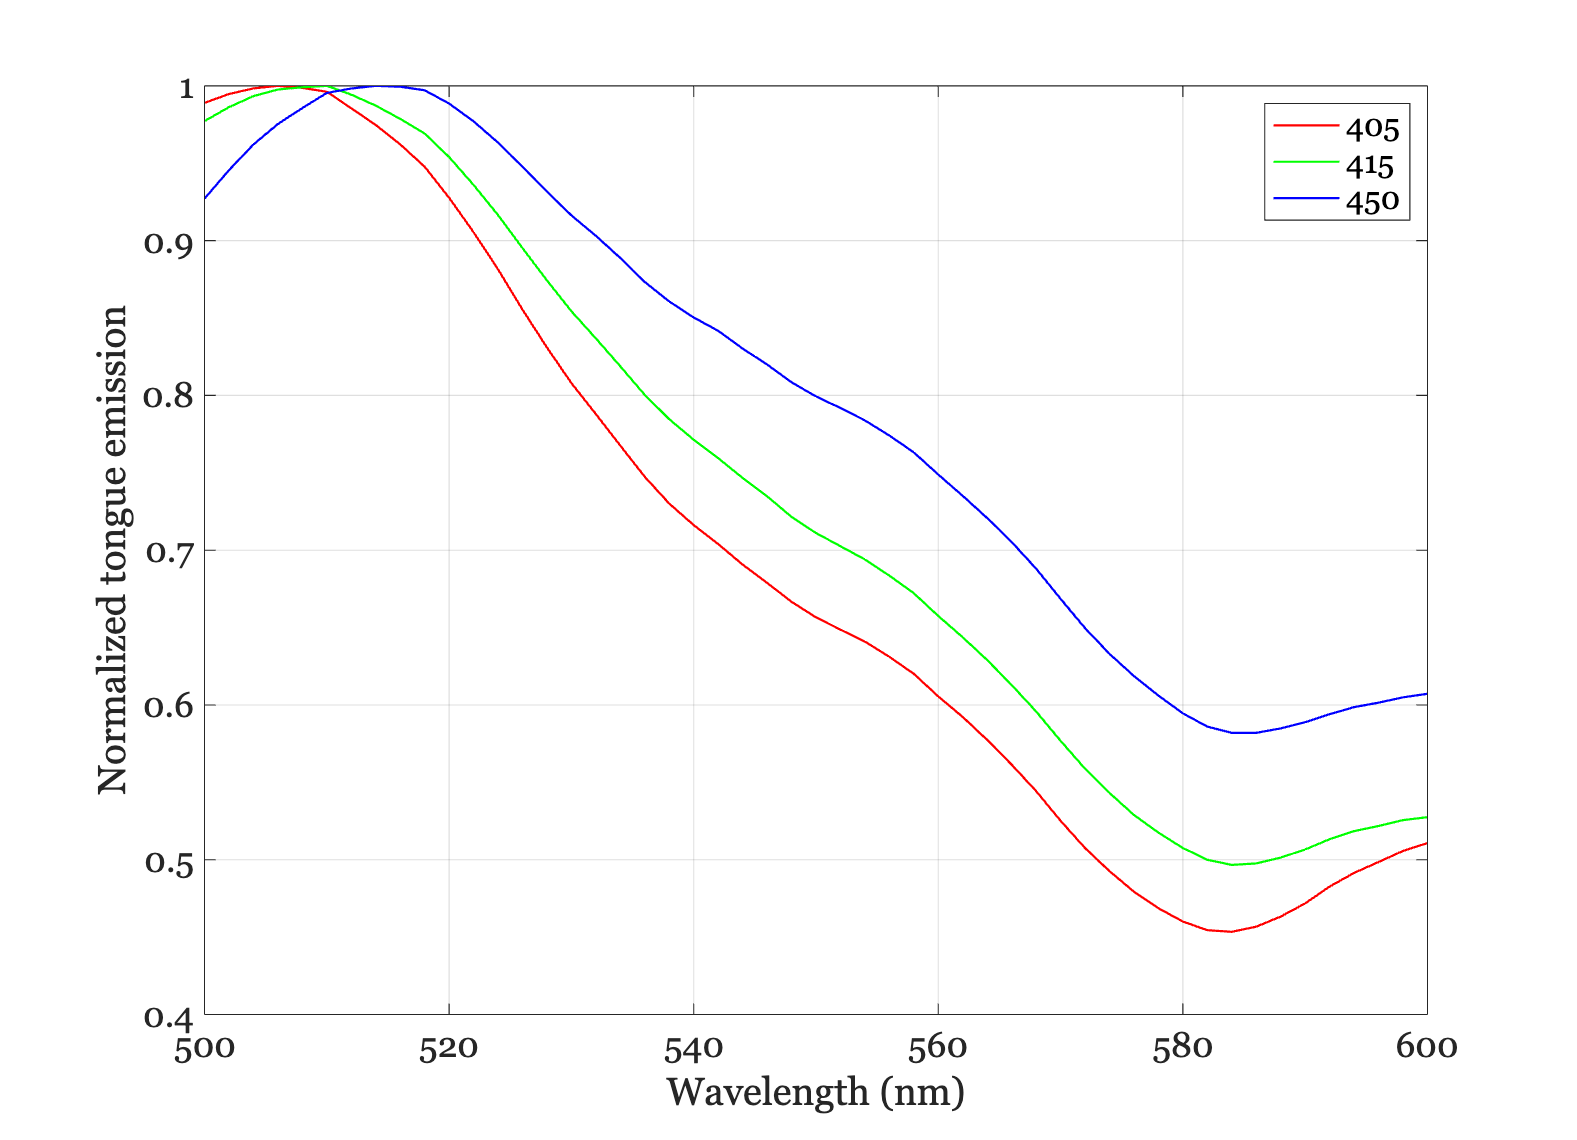

ieNewGraphWin;
tongueFiles = {'spd-2024-03-14-Z-405nm_tongue_980mA.mat'; ...
    'spd-2024-03-14-Z-415nm_Tongue_910mA.mat';
    'spd-2024-03-14-Z-450nm_tongue_870mA.mat'};
tongueData = zeros(numel(wave),numel(tongueFiles));

for ii=1:numel(tongueFiles)
    data = ieReadSpectra(fullfile(dataDir,tongueFiles{ii}),wave); 
    tongueData (:,ii) = data(:);
    plot(wave,data/max(data(:))); hold on;
end
legend({'405','415','450'});
xlabel('Wavelength (nm)'); ylabel('Normalized tongue emission')
grid on;

## Select and combine the fluorophores for a basis

First, let's make a large number of basis functions from the fluorophores and the fluorophores modified by blood.  Let's make sure that we can get very close to the raw data when they are overfit this way.

We will make a list of all the fluorophore emissions in a matrix.  This could become a function, such as

**F = fiBasis( {'filenames of fluorophores'} ,wave)**

fluorophores = [...
    fluorophoreGet(collagenF,'normalized emission','wave',wave)', ...
    fluorophoreGet(elastinF,'normalized emission','wave',wave)', ...
    fluorophoreGet(keratinF,'normalized emission','wave',wave)', ...
    fluorophoreGet(NADHF,'normalized emission','wave',wave)', ...
    fluorophoreGet(FADF,'normalized emission','wave',wave)', ...
    fluorophoreGet(porphyrinsF,'normalized emission','wave',wave)'];
fluorophoreNames = {'Collagen','Elastin','Keratin','NADH','FAD','Porphyrin'};

First, check that the full matrix can predict the data samples.  We think it won't without (a) accounting for blood, and (b) adding some more.  The formula is simple for the full linear calculation


$$d=\mathrm{Fw}$$


This is the completely free method for estimating.

## Lips

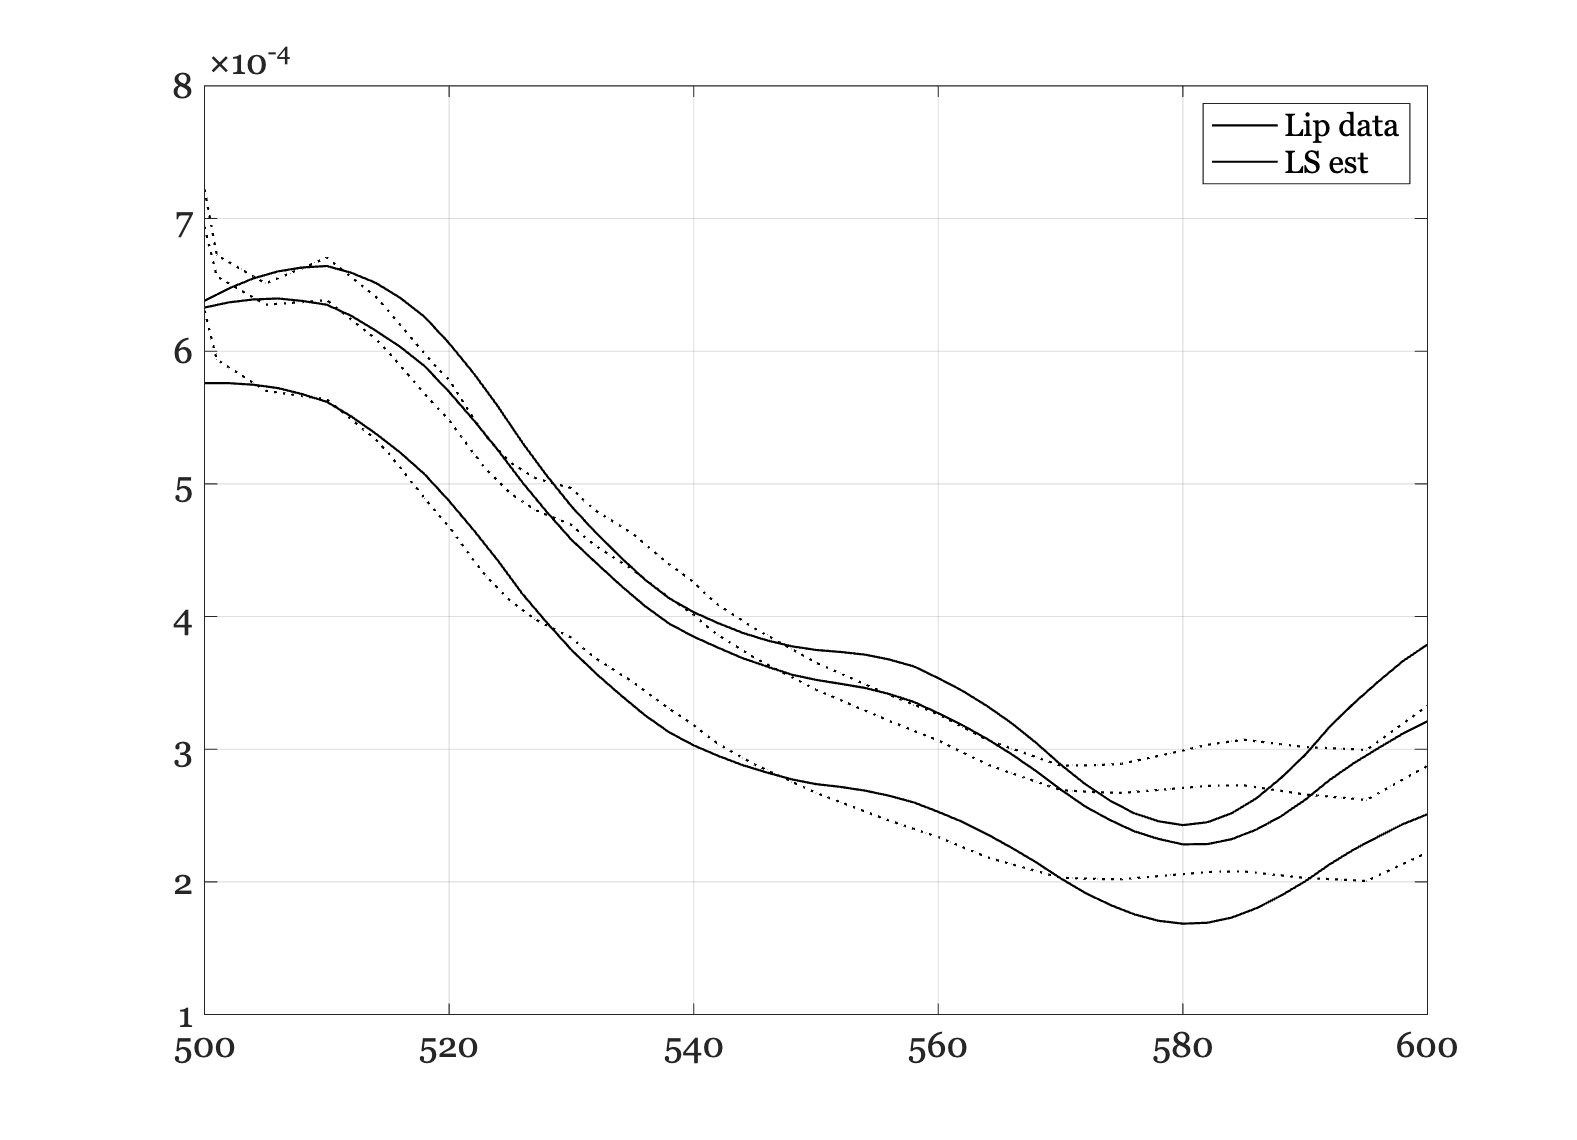

wgtsLS = pinv(fluorophores)*lipData;

ieNewGraphWin;
plot(wave,lipData,'k-',wave,fluorophores*wgtsLS,'k:');
grid on;
legend({'Lip data','LS est'});

This is non-negative method for estimating.  In both cases, the little wavy part misses where the blood absorbance may matter.  In the next section we will put some blood absorbance into certain fluorophores to see if we improve the fit.  

Also, the increase starting around 600 matches the rise of the porphyrins.

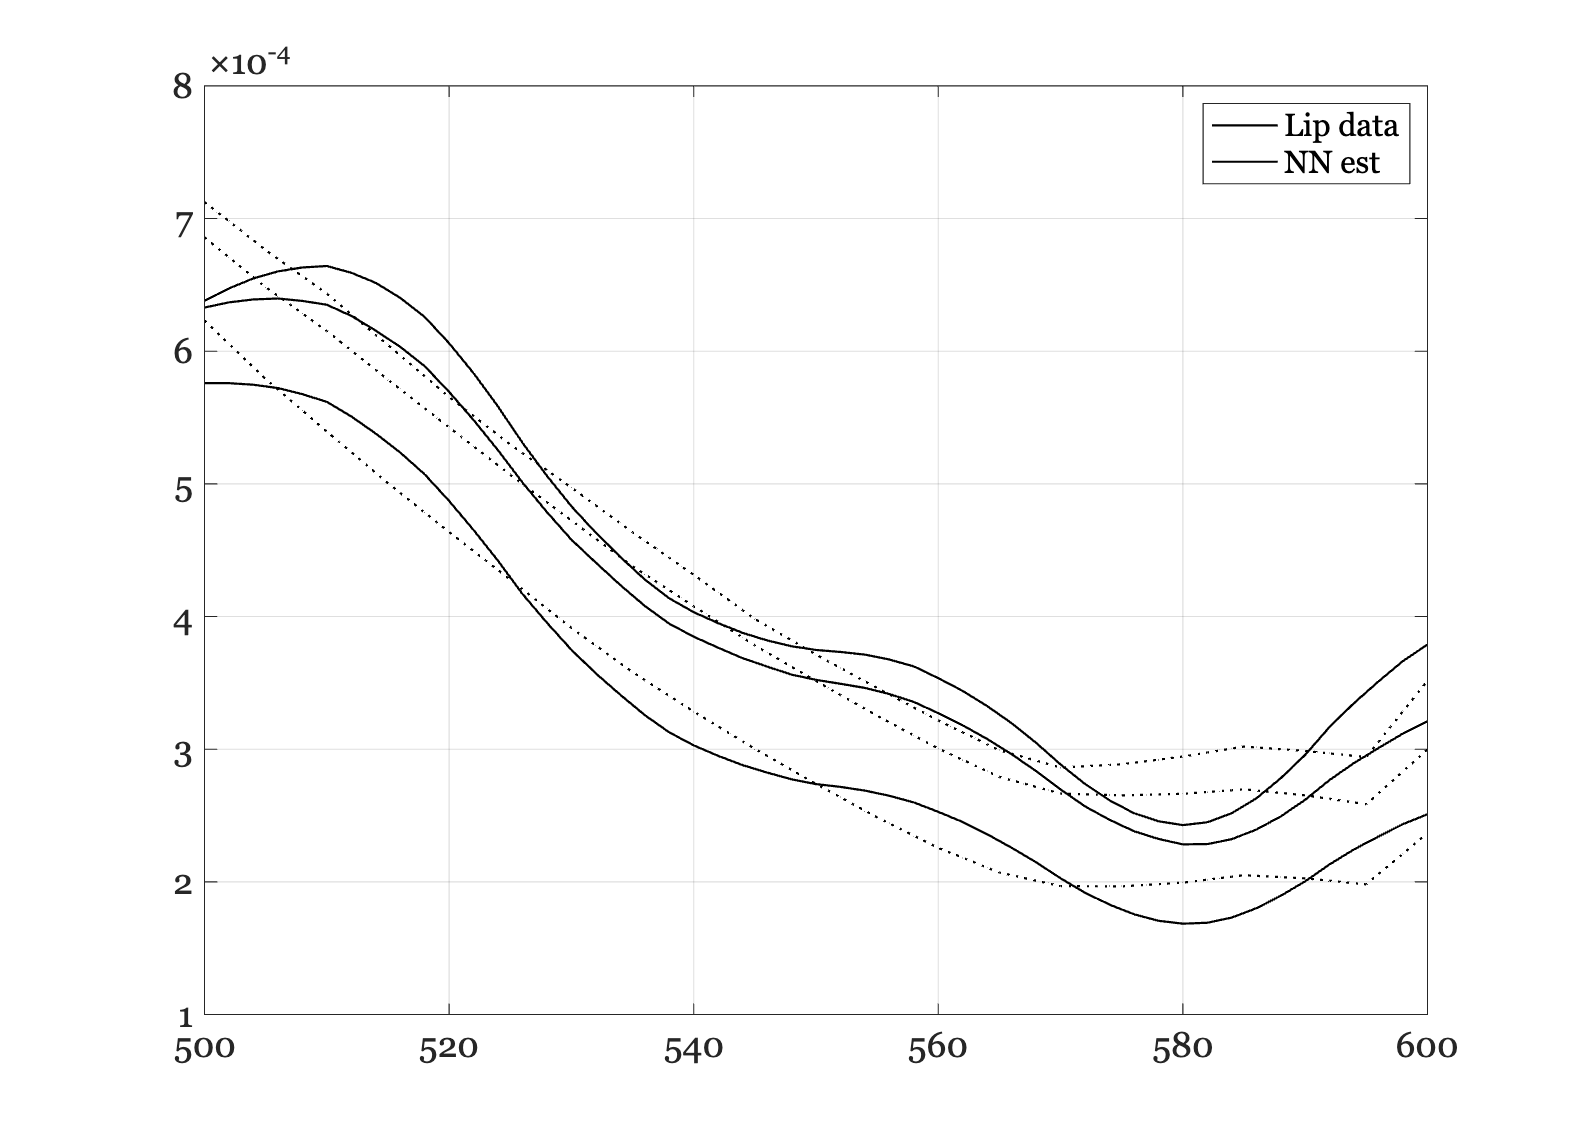

wgtsNN = zeros(size(wgtsLS));
for dd = 1:3
    wgtsNN(:,dd) = lsqnonneg(fluorophores,lipData(:,dd));
end

ieNewGraphWin;
plot(wave,lipData,'k-',wave,fluorophores*wgtsNN,'k:');
grid on;
legend({'Lip data','NN est'});

## Tongue

Least squares

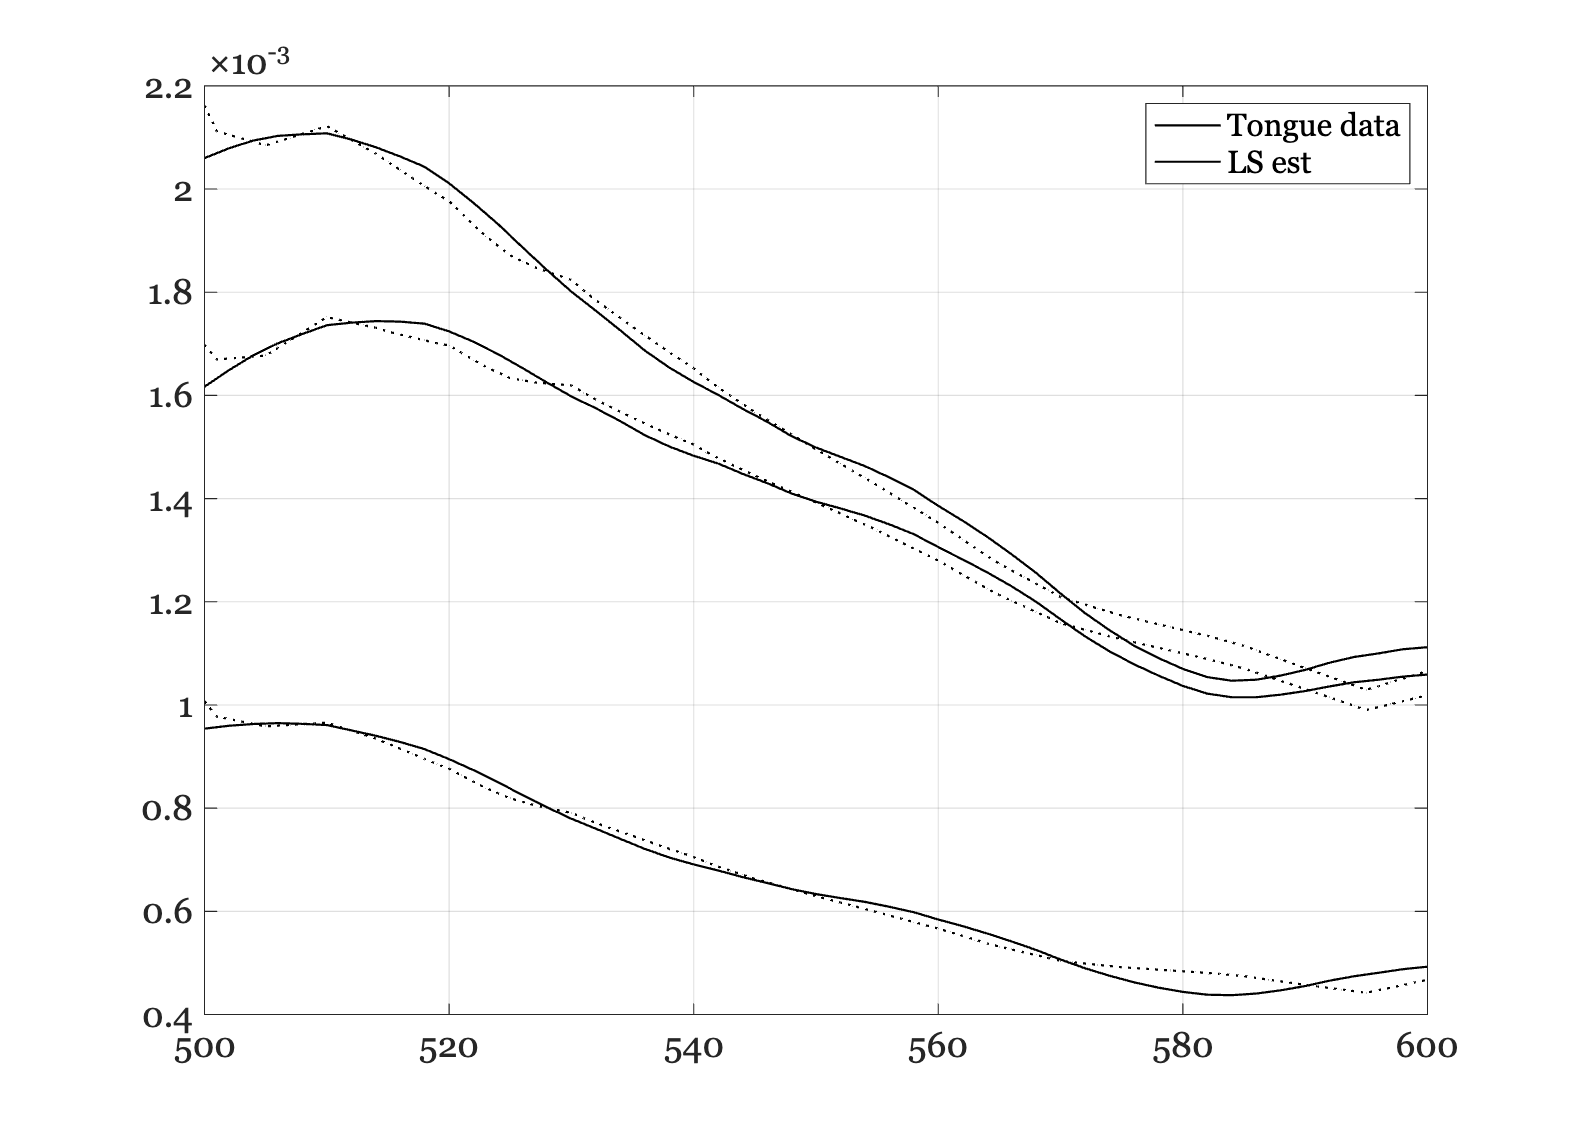

    {'Collagen' }
    {'Elastin'  }
    {'Keratin'  }
    {'NADH'     }
    {'FAD'      }
    {'Porphyrin'}

    0.0011    0.0012    0.0013
    0.0015    0.0019    0.0029
   -0.0017   -0.0021   -0.0033
   -0.0006   -0.0008   -0.0010
   -0.0003   -0.0003   -0.0004
    0.0058    0.0074    0.0087



wgtsLS = pinv(fluorophores)*tongueData;

ieNewGraphWin;
plot(wave,tongueData,'k-',wave,fluorophores*wgtsLS,'k:');
grid on;
legend({'Tongue data','LS est'}); disp(fluorophoreNames'); disp(wgtsLS);

**This is non-negative method for estimating**

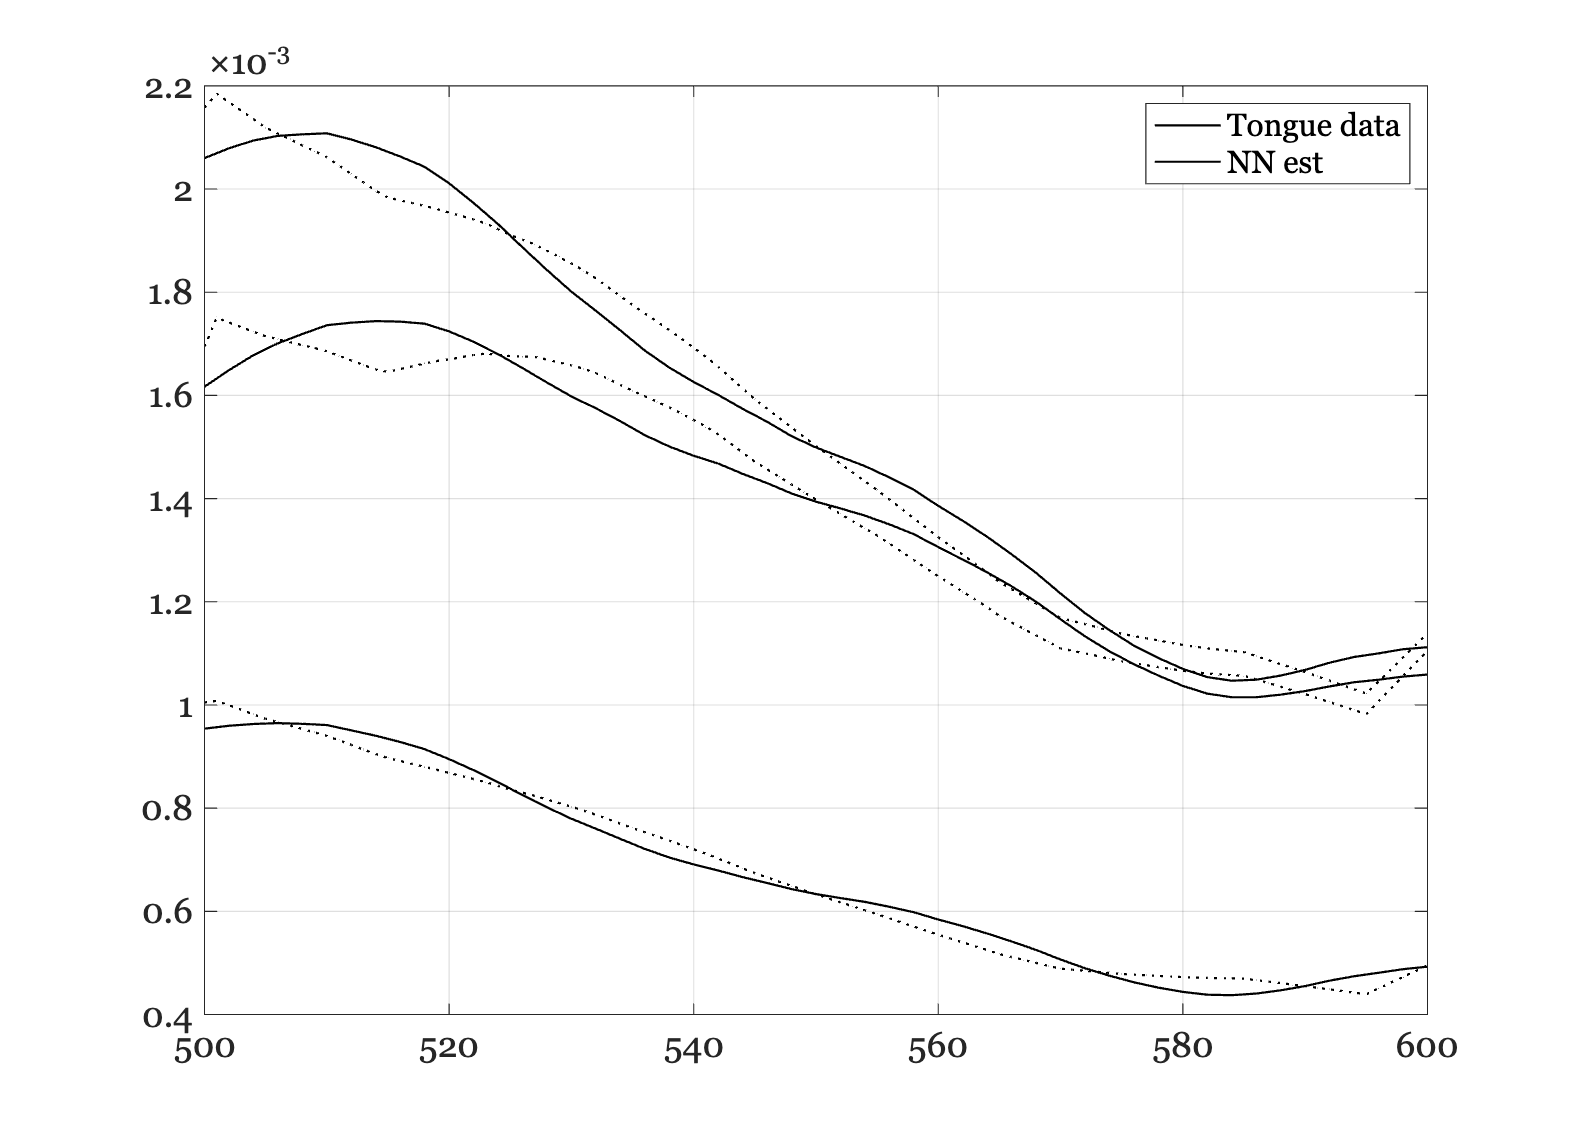

wgtsNN = zeros(size(wgtsLS));

for dd = 1:3
    wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
end

ieNewGraphWin;
plot(wave,tongueData,'k-',wave,fluorophores*wgtsNN,'k:');
grid on;
legend({'Tongue data','NN est'});

disp(fluorophoreNames'); disp(wgtsNN);

    {'Collagen' }
    {'Elastin'  }
    {'Keratin'  }
    {'NADH'     }
    {'FAD'      }
    {'Porphyrin'}

    0.0009    0.0020    0.0020
    0.0002    0.0005    0.0000
         0         0         0
         0         0         0
    0.0001    0.0004    0.0005
    0.0191    0.0420    0.0430



## Fitting

Find a solution subject to (a) L1 norm, (b) L2 regularized for smoothness.  Deal with non-negativity as well.